# Problem 2.3.3

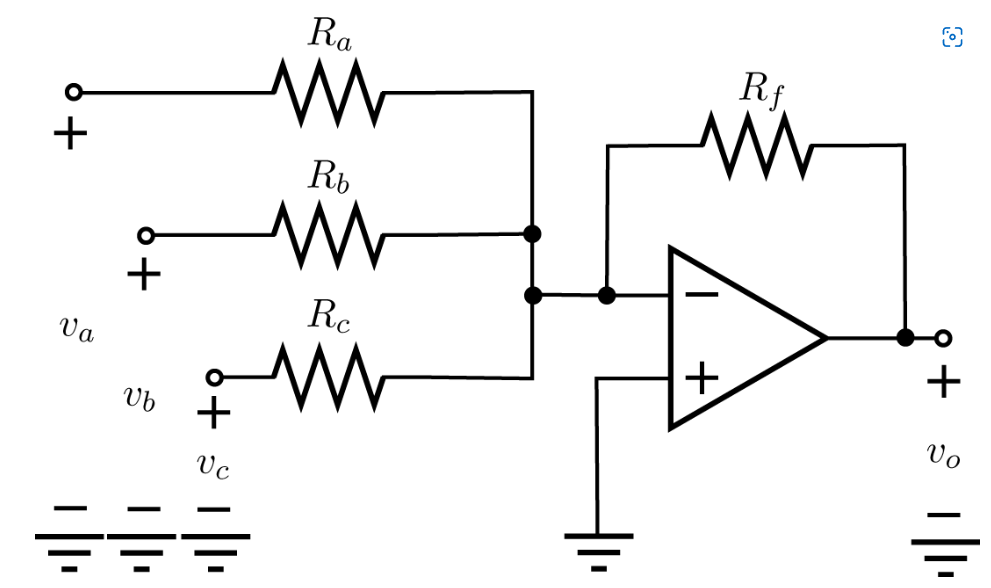

Given the above circuit, where:

- 
$$R_a=1k\Omega
$$


- 
$$R_b=2k\Omega
$$


- 
$$R_c=3k\Omega
$$


- 
$$R_f=12k\Omega
$$


- 
$$v_a=-4V
$$


- 
$$v_b=+2V
$$


- 
$$v_c=1V
$$


The power supplies for the op-amp are +15V and −15V.  What is the value of $v_o$?

While


$$v_o=G_{1}v_a+G_{2}v_b + G_{3}v_c
$$


$G_1=-\frac{R_f}{R_a}
$, $G_2=-\frac{R_f}{R_b}
$, $G_3=-\frac{R_f}{R_c}
$.

Therefore 

Ra = 1e3;
Rb = 2e3;
Rc = 3e3;
Rf = 12e3;
va = -4;
vb = 2;
vc = 1;
v_o = (-Rf/Ra)*va ...
      + (-Rf/Rb)*vb ...
      + (-Rf/Rc)*vc

v_o = 32


$$v_o=32V$$


The calculated output voltage is greater than 15 so saturation occurs and $v_o$ is equal to the power supply voltage of 15 volts.

What must be $R_a$ be changed to so that $v_o=13V$?

syms Ra
f(Ra) = (-Rf/Ra)*va ...
      + (-Rf/Rb)*vb ...
      + (-Rf/Rc)*vc == 13;
% Compute analytic solution of a symbolic equation
solution = solve(f,Ra);
% Display symbolic solution returned by solve
displaySymSolution(solution);

$$solution = \frac{48000}{29}$$


$$R_a=1.6552k\Omega
$$
